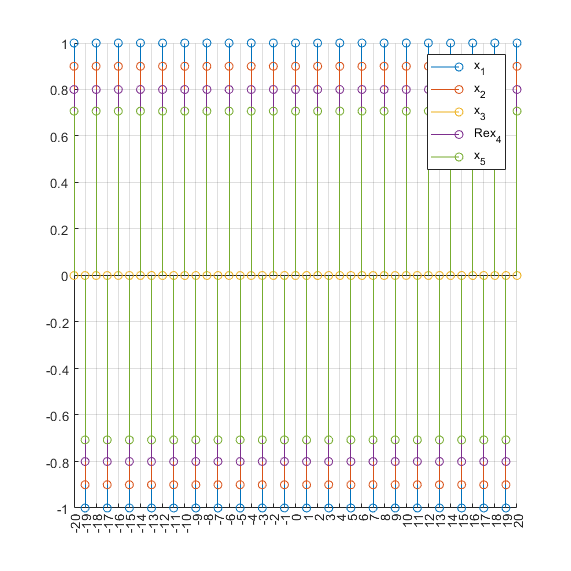

% visit the link below to learn plotting discrete graphs
% https://www.mathworks.com/help/matlab/ref/stem.html

sampleCou = 20;
global nArr
nArr = -sampleCou:1:sampleCou; % array to store discrete samples

% signals
x_1 = j .^ (-2*nArr);
x_2 = 0.9*cos(pi * nArr); % scaled by 0.9 to prevent overlapping with x_1
x_3 = sin(-pi * nArr);
x_4 = 0.8*exp((j * 9 * pi) .* nArr); % scaled by 0.8 to prevent overlapping with x_1
x_5 = cos( (pi * nArr) + (pi/4) );
x_6 = cos(nArr);
x_7 = sin(nArr);

% plotting
handleBeforePlot()
stem(nArr, x_1)
stem(nArr, x_2)
stem(nArr, x_3)
stem(nArr, real(x_4))
stem(nArr, x_5)
% stem(nArr, imag(x_4)) % This is 0. No need to plot
legend('x_1', 'x_2', 'x_3', 'Re{x_4}', 'x_5') %, 'Im{x_4}')
hold off
set(gcf, 'Position', [0 0 800 800]); % set the resolution of the current graph
saveas(gcf, '1-5.png') % save the current graph to local drive

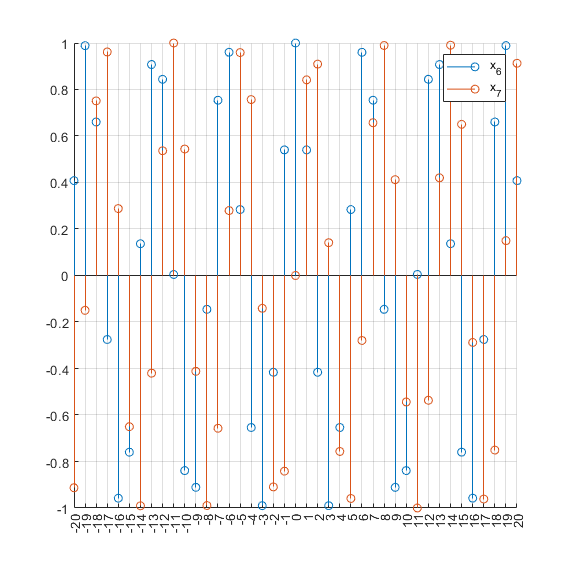


handleBeforePlot()
stem(nArr, x_6)
stem(nArr, x_7)
legend('x_6', 'x_7')
hold off
set(gcf, 'Position', [0 0 800 800]); % set the resolution of the current graph
saveas(gcf, '6-7.png') % save the current graph to local drive

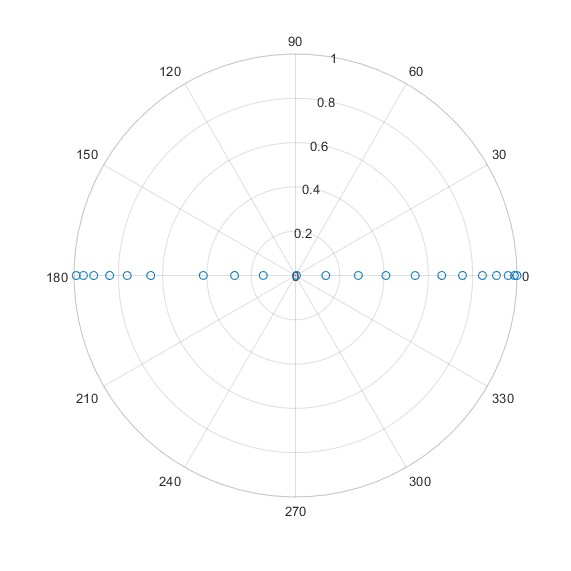


%%%%%%%%%%%%%%%%%% Polar plotting %%%%%%%%%%%%%%%%%%
% https://www.mathworks.com/help/matlab/ref/polarplot.html
figure()
x_6Real = x_6;
x_6Imag = j*zeros(1, 2*sampleCou + 1);
x_6 = x_6Real + x_6Imag;
polarscatter(angle(x_6), abs(x_6))
set(gcf, 'Position', [0 0 800 800]); % set the resolution of the current graph
saveas(gcf, '6_polar.png') % save the current graph to local drive

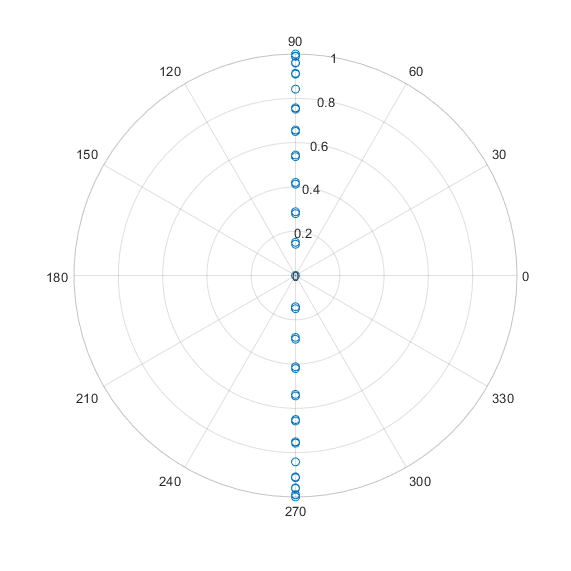


figure()
x_7Imag = j*x_7;
x_7Real = zeros(1, 2*sampleCou + 1);
x_7 = x_7Real + x_7Imag;
polarscatter(angle(x_7), abs(x_7))
set(gcf, 'Position', [0 0 800 800]); % set the resolution of the current graph
saveas(gcf, '7_polar.png') % save the current graph to local drive

Beyond Quiz 

#### 
$$x\left\lbrack n\right\rbrack =C{\mathrm{e}}^{\beta n} \;\textrm{where}\;\alpha =e^{\beta }$$


% https://www.mathworks.com/matlabcentral/answers/78973-semi-log-stem-plot
% https://www.mathworks.com/matlabcentral/answers/1792-log-scale-graphic-with-negative-value
n = -10:1:25;
C = 4 + 3j;
beta = 2 + j;
alpha = exp(beta)

alpha = 3.9923 + 6.2177i

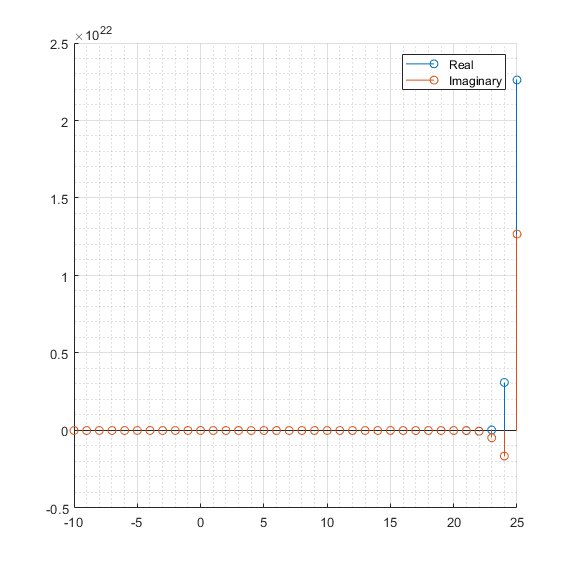

sigX = C*exp(beta*n);

handleBeforePlot2()
stem(n, real(sigX))
stem(n, imag(sigX))
hold off
legend('Real', 'Imaginary')
set(gcf, 'Position', [0 0 800 800]); % set the resolution of the current graph
saveas(gcf, 'growingSinusoid.png') % save the current graph to local drive

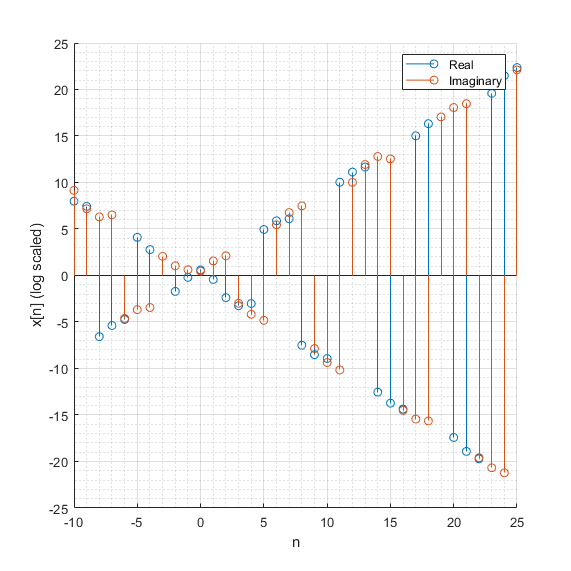


handleBeforePlot2()
stem(n, sign(real(sigX)) .* log10(abs(real(sigX))) )
stem(n, sign(imag(sigX)) .* log10(abs(imag(sigX))) )
hold off
legend('Real', 'Imaginary')
xlabel('n')
ylabel('x[n] (log scaled)')
set(gcf, 'Position', [0 0 800 800]); % set the resolution of the current graph
saveas(gcf, 'growingSinusoid-log.png') % save the current graph to local drive

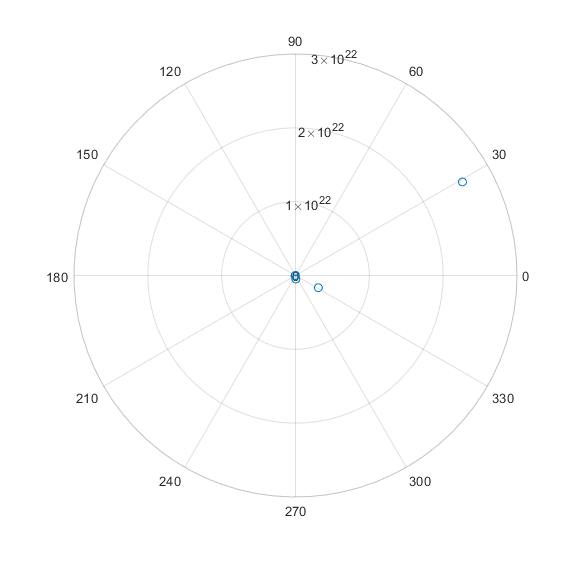


figure()
polarscatter(angle(sigX), abs(sigX))
% rlim([0 1e3])
set(gcf, 'Position', [0 0 800 800]); % set the resolution of the current graph
saveas(gcf, 'growingSpiral.png') % save the current graph to local drive

function handleBeforePlot()
    global nArr
    figure()
    hold on
    grid on
    % grid minor
    xticks(nArr)
end

function handleBeforePlot2()
    global nArr
    figure()
    hold on
    grid on
    grid minor
end